# Project2 : Motion detection via communication signals

涂峻绫(12213010), 欧阳莹轩(12212961), 肖星辰(12212904), 欧阳安男(12211831)

## Introduction

## Results and Analysis

### Task 1

- For the reference signal and the surveillance signal, draw their time domain waveforms and their frequency domain waveforms.

Initialize and load audio to $ref$ and $sur$.

clear;clc;
load('proj2/data_1.mat');
t = 1/f_s : 1/f_s : 0.5;
t_ms = t*1000;
ref = seq_ref;
sur = seq_sur;

Do Digital Down Convert (DDC).

f_ddc = -3e6;
ref_ddc = ref .* exp(-1i * 2*pi * f_ddc * t);
sur_ddc = sur .* exp(-1i * 2*pi * f_ddc * t);

Do Low Pass Filter (LPF).

f_cutoff = 9e6;
[b,a] = butter(24, f_cutoff/(f_s/2));
ref_lpf = filter(b, a, ref_ddc);
sur_lpf = filter(b, a, sur_ddc);

Calculate spectrum.

freq_mhz = 2110-2123+2e-6 : 2e-6 : 2135-2123;
sur_freq = abs(fftshift(fft(sur)));
sur_ddc_freq = abs(fftshift(fft(sur_ddc)));
sur_lpf_freq = abs(fftshift(fft(sur_lpf)));
ref_freq = abs(fftshift(fft(ref)));
ref_ddc_freq = abs(fftshift(fft(ref_ddc)));
ref_lpf_freq = abs(fftshift(fft(ref_lpf)));

Convert to dB.

ref_freq = 20 * log10(ref_freq / max(sur_freq));
ref_ddc_freq = 20 * log10(ref_ddc_freq / max(sur_ddc_freq));
ref_lpf_freq = 20 * log10(ref_lpf_freq / max(sur_lpf_freq));
sur_freq = 20 * log10(sur_freq / max(sur_freq));
sur_ddc_freq = 20 * log10(sur_ddc_freq / max(sur_ddc_freq));
sur_lpf_freq = 20 * log10(sur_lpf_freq / max(sur_lpf_freq));

Plot.

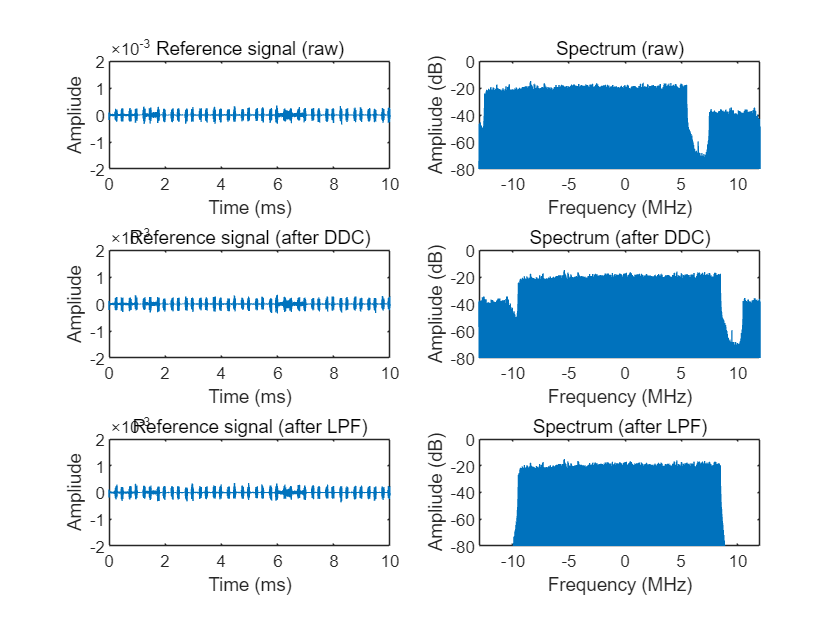

figure;
task1plot(1, 'Reference signal (raw)', t_ms, real(ref), true);
task1plot(3, 'Reference signal (after DDC)', t_ms, real(ref_ddc), true);
task1plot(5, 'Reference signal (after LPF)', t_ms, real(ref_lpf), true);
task1plot(2, 'Spectrum (raw)', freq_mhz, ref_freq, false);
task1plot(4, 'Spectrum (after DDC)', freq_mhz, ref_ddc_freq, false);
task1plot(6, 'Spectrum (after LPF)', freq_mhz, ref_lpf_freq, false);

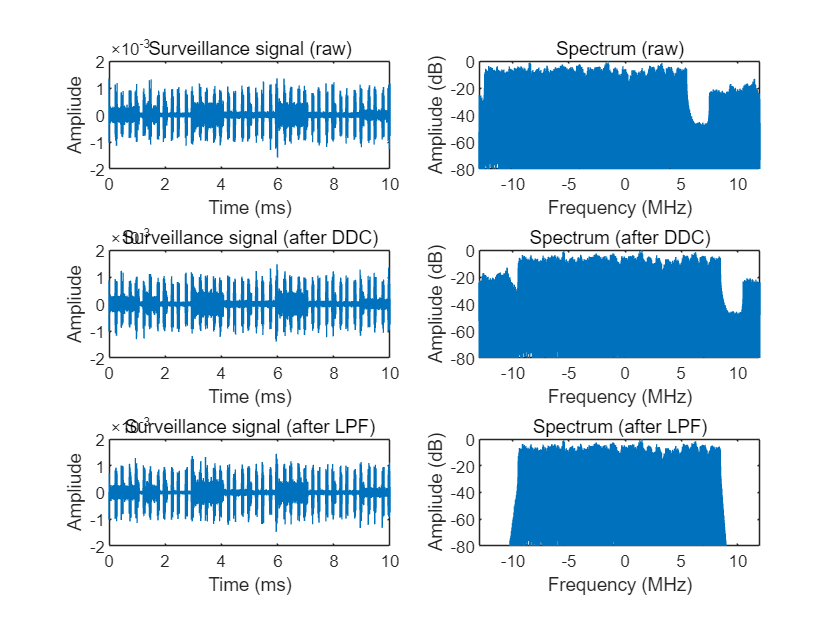

figure;
task1plot(1, 'Surveillance signal (raw)', t_ms, real(sur), true);
task1plot(3, 'Surveillance signal (after DDC)', t_ms, real(sur_ddc), true);
task1plot(5, 'Surveillance signal (after LPF)', t_ms, real(sur_lpf), true);
task1plot(2, 'Spectrum (raw)', freq_mhz, sur_freq, false);
task1plot(4, 'Spectrum (after DDC)', freq_mhz, sur_ddc_freq, false);
task1plot(6, 'Spectrum (after LPF)', freq_mhz, sur_lpf_freq, false);

#### Description

### Task 2

- Plot the Range Doppler spectrum of the signal located at 0-0.5s, 2-2.5s, 5-5.5s and 7-7.5s.

clear;clc;
load('proj2/data_1.mat');
t = 1/f_s : 1/f_s : 0.5;
t_ms = t*1000;
ref = seq_ref;
sur = seq_sur;

Calculate the minimum $\tau$ and $f_D$

light_speed = 3e8;
tau = 0 : 12/light_speed : 72/light_speed;
fd = -40:2:40;
[cor, corMax] = Cor(tau, fd, 0.5, 125e5, sur, ref, 0);
corMax

corMax = 0

figure;
imagesc(fd, tau*light_speed, cor);
clim([-10 0]);
colorbar
set(gca,'Ydir','normal');
title("Range-Doppler Spectrum [ 0.0s: 12m 4Hz ]");
xlabel("Doppler frequency (Hz)");
ylabel("Range (m)");
axis([-40 40 0 72]);
yticks(0:12:72);

#### Description

### Task 3

- Plot the T ime Doppler spectrum with coherent integration time (CIT) equal to 0.5s. Time range is 0-9.5s.

#### Description

### Functions

The function to plot in task1.

function task1plot(plot_idx, title_name, x, y, is_t_domain)
subplot(3, 2, plot_idx);
plot(x, y);
title(title_name);
if is_t_domain
    xlabel('Time (ms)');
    ylabel('Ampliude');
    axis([0 10 -2e-3 2e-3]);
    xticks(0:2:10);
    yticks((-2:2)*1e-3);
else
    xlabel('Frequency (MHz)');
    ylabel('Ampliude (dB)');
    axis([-13 12 -80 0]);
    yticks(-80:20:0);
end
end

Function to $Cor(\tau, f_D, t_0)$ for task2.

function [cor, corMax]= Cor(tau, fd, T, N, sur, ref, t0)
cor = zeros(length(fd),length(tau));
Ts = T/N;
fs = 1/Ts;
offset = t0 / Ts;
for index_fd = 1:length(fd)
    for index_tau = 1:length(tau)
        ref_enh = conj([ref ref]);
        for n = 1 : length(ref)/N : length(ref)
            %if (tau(index_tau)<1)
            %    ref_cur = 0;
            %else
            %    ref_cur = conj(ref(tau(index_tau)));
            %end
            cor(index_fd,index_tau) = cor(index_fd,index_tau) + sur(n + offset) * ref_enh(length(ref) + n - tau(index_tau)*N/T + offset) * exp(-1i*2*pi*(fd(index_fd)/fs)*(n-1));
            %cor(index_fd,index_tau) = cor(index_fd,index_tau) + sur(n + offset) * ref_cur * exp(-1i*2*pi*(fd(index_fd)/fs)*(n-1));
        end
    end
end
cor = real(cor.*Ts);
corMax = max(max(cor));
%[index_tauMax, index_fdMax] = find(corMax == cor);
%tauMax = tau(index_tauMax-1);
%fdMax = fd(index_fdMax-1);
end

Functino to $g(f_D,t_0)$ in task3.

function cor = Time_Doppler(tau, fd, sur, ref)
cor = Cor(tau, fd, 0.1, 25e5, sur, ref)
end

### Summary

## Expeience

........................